clear all; close all
%load("measurement_psd.mat")
%load("measurement_psd_v2.mat")
%load("Measurement_performance.mat")
load('Measurement_performance_v3.mat')

e = measurement_performance_v3;
%removing useless data 
N_trash = 25e3; 
limit = 0.03

limit = 0.0300

e =e(N_trash:end)

e =    -0.0157
   -0.0157
   -0.0157
   -0.0157
   -0.0157
   -0.0157
   -0.0157
   -0.0157
   -0.0157
   -0.0157


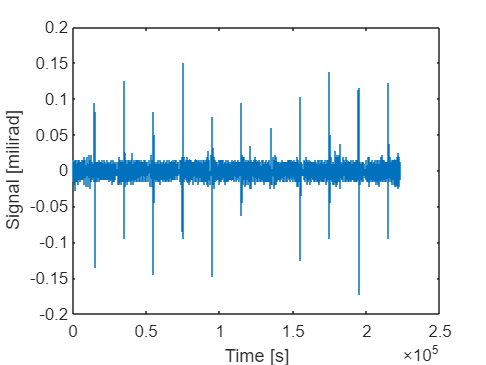

%e(e>limit) = 0.03;
%e(e<-limit) = -0.03;

figure();
stairs(e);
xlabel('Time [s]'); ylabel('Signal [milirad]');
hold off




rms = rms(e)*1e3 %[mrad]

rms = 11.7522

peak = max(abs(e))*1e3 %[mrad] %dit is niet tijdens constant velocity

peak = 172.7876

% Plot the measurement


%data analysis
fs = 4000 %[Hz]

fs = 4000

stepsize = 1/fs %[s]

stepsize = 2.5000e-04

max_freq = log10(fs/2) 

max_freq = 3.3010



%window settings
min_freq = 0.1; %[Hz/s] lowest desired sampling frequency
windowsize = 1/min_freq; %[s] window size in seconds

nfft = round(windowsize*fs) %window size in data points 

nfft = 40000

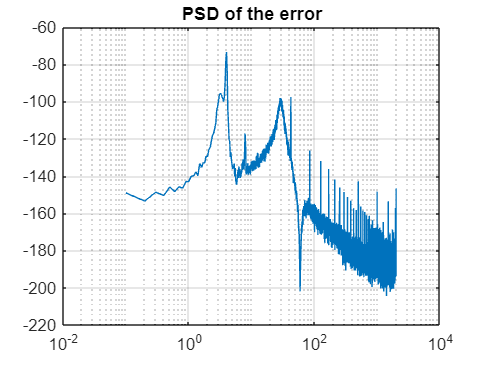

n_overlap = round(nfft/3);

%Tf estimate
[psd_e, F] = pwelch(e,hann(nfft),n_overlap,nfft,fs,'psd'); %spectral power disturbance

figure()
semilogx(F,mag2db(abs(psd_e)))
title("PSD of the error")
grid on; hold off


N = length(e);
xdft = fft(e);
xdft = xdft(1:N/2+1);

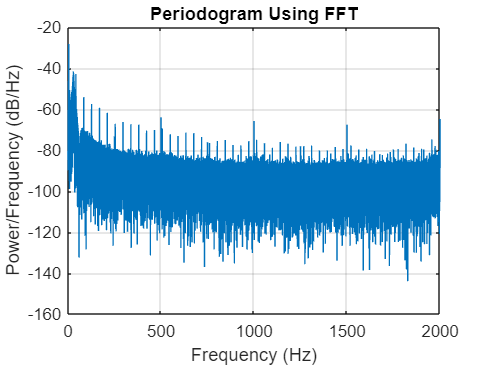

psdx = (1/(fs*N)) * abs(xdft).^2;
psdx(2:end-1) = 2*psdx(2:end-1);
freq = 0:fs/length(e):fs/2;

plot(freq,pow2db(psdx))
grid on
title("Periodogram Using FFT")
xlabel("Frequency (Hz)")
ylabel("Power/Frequency (dB/Hz)")